M = 16;                     %Comment
k = log2(M);                %
n = 30000;                  %
numSamplePerSymbol = 1;     %

rng default;

rng('default') は、rand、randi および randn で使用される乱数発生器の設定を既定値に指定します。これにより、MATLAB を再起動したかのように、同じ乱数が生成されます。既定の設定は、seed が 0 のメルセンヌ・ツイスターです。

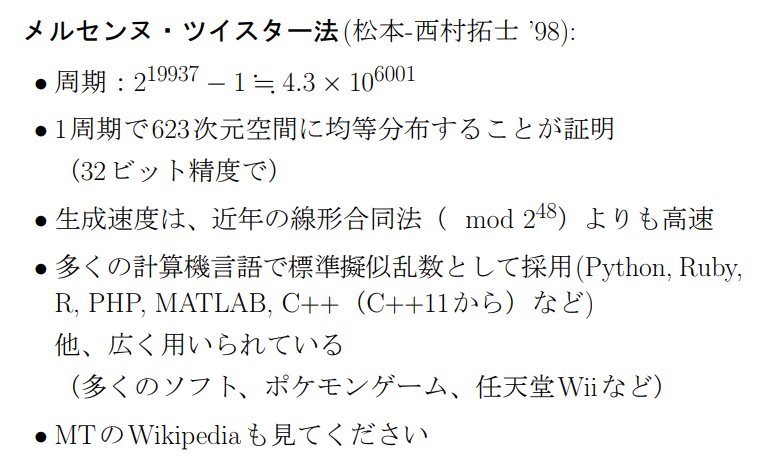

dataIn = randi([0,1],n,1); % 0 ~ 1 の間の値でランダムにn個出力。データのステップは1。

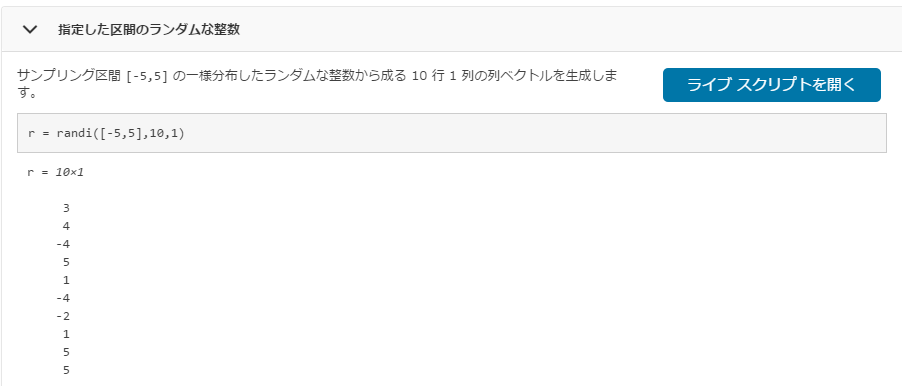

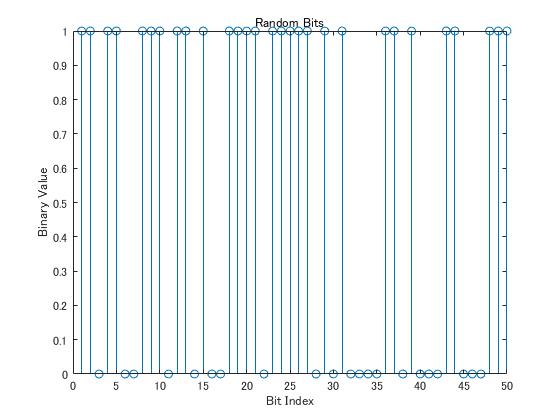

stem(dataIn(1:50)); %離散データ列のプロット
title('Random Bits');
xlabel('Bit Index');
ylabel('Binary Value');

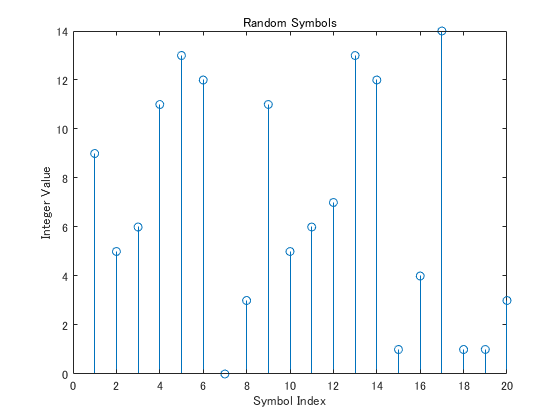

dataInMatrix = reshape(dataIn,length(dataIn)/k,k); %reshapeは次元変更関数：dataIn(30000行1列)を30000行k列に変換
dataSymbolsIn = bi2de(dataInMatrix); %2進数から10進数への変換

figure;
stem(dataSymbolsIn(1:20));
title('Random Symbols');
xlabel('Symbol Index');
ylabel('Integer Value');

dataMod = qammod(dataSymbolsIn,M,'bin');
dataModG = qammod(dataSymbolsIn,M); %シンボル順序のデフォルトはGray

EbN0 = 10;
snr = EbN0 + 10*log10(k) - 10*log10(numSamplePerSymbol)

snr = 16.0206

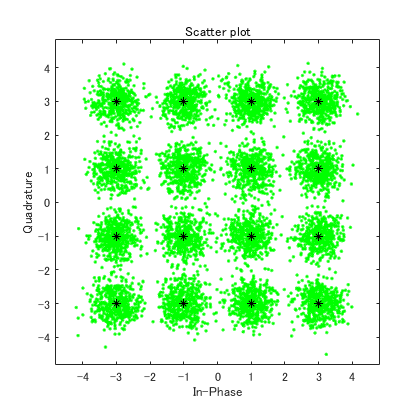


receivedSignal = awgn(dataMod,snr,'measured');
receivedSignalG = awgn(dataModG,snr,'measured');

sPlot1 = scatterplot(receivedSignal,1,0,'green.');
hold on
sPlot2 = scatterplot(dataMod,1,0,'black*',sPlot1);

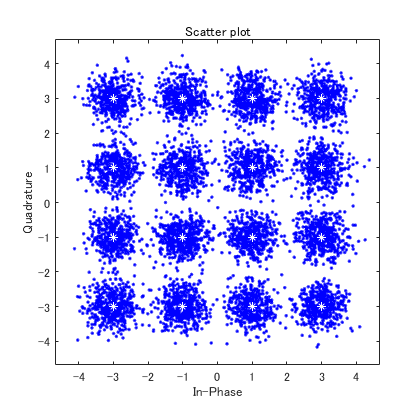

sPlot1G = scatterplot(receivedSignalG,1,0,'b.');
hold on
sPlot2G = scatterplot(dataModG,1,0,'white*',sPlot1G);

dataSymbolsOut = qamdemod(receivedSignal,M,'bin');
dataSymbolsOutG = qamdemod(receivedSignalG,M);

dataOutMatrix = de2bi(dataSymbolsOut,k);
dataOut = dataOutMatrix(:);